随机森林

clc
clear
figure(1)
subplot(1,2,1)
x = [1:1:13];
dataset = [0.04 0.04 0.04 0.043 0.046 0.053 0.056 ...
    0.058 0.06 0.066 0.068 0.079 0.114];
%% 颜色定义
map = addcolorplus(297);
idx = linspace(1,64,13);
idx = round(idx);
C = map(idx,:);
%% 绘制多色单组柱状图
GO = barh(x,dataset,0.6,'EdgeColor','k','LineWidth', 1);
hXLabel = ylabel('Variable');
hYLabel = xlabel('Significance-RF');

%% 细节优化
% 赋色
GO.FaceColor = 'flat';
for i = 1:13
    GO.CData(i,:) = C(i,:);
end

% 坐标区调整
set(gca, 'Box', 'off', ...                                         % 边框
         'LineWidth', 1, 'GridLineStyle', '-',...                  % 坐标轴线宽
         'YGrid', 'off', 'XGrid', 'on', ...                       % 网格
         'TickDir', 'out', 'TickLength', [.015 .015], ...          % 刻度
         'XMinorTick', 'off', 'YMinorTick', 'off', ...             % 小刻度
         'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1],...           % 坐标轴颜色
         'XTick', 0:0.04:0.12,...                                      % 刻度位置、间隔、范围
         'Xlim' , [0 0.12], ...                                     
         'Ylim' , [0.3 13.7], ...
         'YTick', 1:13,...
         'Yticklabel',{'CD4/8','EBV-VCA-M','Heterolymphocyte ','CD3+CD4+%',...
         'IgG','ALT',...
    'N','CD3+CD8+%','WBC','EB-DNA copy Number',...
    'PLT','LDH','AST'},...                                   % X坐标轴刻度标签
         'Xticklabel',{[0:0.04:0.12]})                                 % Y坐标轴刻度标签
% 字体和字号
set(gca, 'FontName', 'times')
set([hXLabel, hYLabel], 'FontName', 'times')
set(gca, 'FontSize', 18)
set([hXLabel, hYLabel], 'FontSize', 24)
% 背景颜色
set(gcf,'Color',[1 1 1])

xgboost

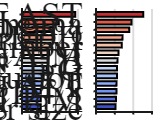

clc
clear
figure(1)
subplot(1,2,2)
x = [1:1:13];
dataset = [0.042 0.043 0.044 0.044 0.045 0.045 0.046 ...
    0.048 0.055 0.057 0.071 0.076 0.101];
%% 颜色定义
map = addcolorplus(297);
idx = linspace(1,64,13);
idx = round(idx);
C = map(idx,:);
%% 绘制多色单组柱状图
GO = barh(x,dataset,0.6,'EdgeColor','k','LineWidth', 1);
hYLabel = xlabel('Significance-Xgboost');

%% 细节优化
% 赋色
GO.FaceColor = 'flat';
for i = 1:13
    GO.CData(i,:) = C(i,:);
end

% 坐标区调整
set(gca, 'Box', 'off', ...                                         % 边框
         'LineWidth', 1, 'GridLineStyle', '-',...                  % 坐标轴线宽
         'YGrid', 'off', 'XGrid', 'on', ...                       % 网格
         'TickDir', 'out', 'TickLength', [.015 .015], ...          % 刻度
         'XMinorTick', 'off', 'YMinorTick', 'off', ...             % 小刻度
         'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1],...           % 坐标轴颜色
         'XTick', 0:0.04:0.12,...                                      % 刻度位置、间隔、范围
         'Xlim' , [0 0.12], ...                                     
         'Ylim' , [0.3 13.7], ...
         'YTick', 1:13,...
         'Yticklabel',{'Liver size','IgM','CD4/8','ALT',...
         'Tonsillar effusion','IgG',...
    'TB','EBV-VCA-M','EB-DNA copy Number','LDH',...
    'CD3+CD8+%','Angina','AST'},...                                   % X坐标轴刻度标签
         'Xticklabel',{[0:0.04:0.12]})                                 % Y坐标轴刻度标签
% 字体和字号
set(gca, 'FontName', 'times')
set(hYLabel, 'FontName', 'times')
set(gca, 'FontSize', 18)
set(hYLabel, 'FontSize', 24)

% 背景颜色
set(gcf,'Color',[1 1 1])
